Create an audiorecorder object named recObj for recording audio input.

Properties audiorecorder

%Fs=8000;
Fs=11025;

Nbits=8;
Ncha=1;
recObj = audiorecorder(Fs,Nbits,Ncha)

recObj =   audiorecorder with properties:

       SampleRate: 11025
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


Record your voice for T seconds.

disp('Start speaking.')

Start speaking.


T=4;
recordblocking(recObj, T);
disp('End of Recording.');

End of Recording.


Play back the recording.

play(recObj);


Store data in double-precision array, y.


y = getaudiodata(recObj);

Plot the audio samples.

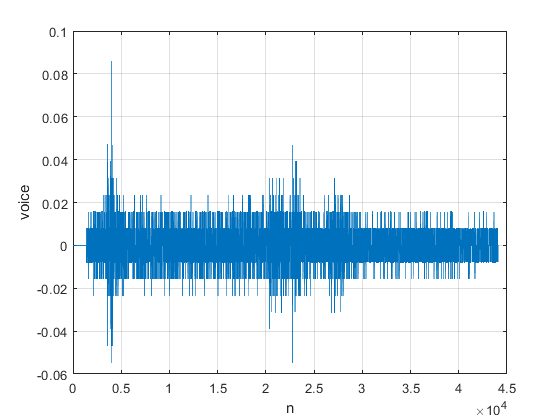


plot(y); grid on; xlabel('n'); ylabel('voice')